# Implementing Nonlinear MPC with CasADi

**Goal: **Given the measured state $x\left(k\right)=x_k$, find the optimal input sequence $u^{\star } \left(k\right),\ldotp \ldotp \ldotp ,u^{\star } \left(k+N-1\right)$that steers the system state $x$ towards its equilibrium $\bar{x}$ while respecting the constraints.

- Denote $\left(\bar{x} ,\bar{u} \right)$ the equilibrium of the system such that ${\bar{h} }_1 =h_1^{\mathrm{ref}} \left(k\right)$, è il punto in cui vogliamo far andare il sistema perchè in questo modo tracciamo il riferimento.

One of the possible nonlinear MPC formulation is the following

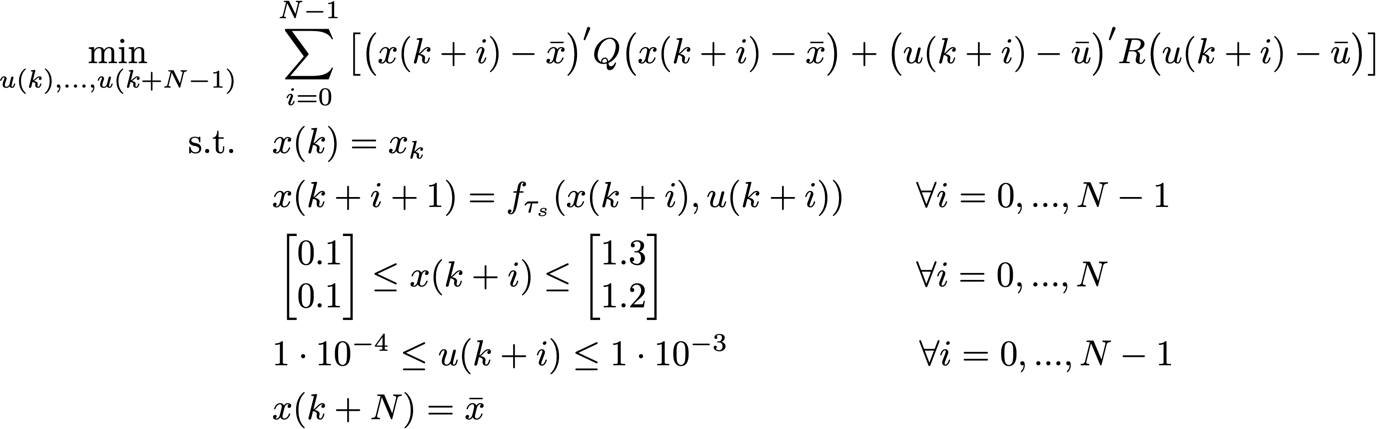

x(k)=x_k significa che lo stato all' instante k deve essere uguale a quello misurato nello stesso istante.

x(k+i+1)=...vincolo che indica che dobbiamo soddisfare la dinamica del sistema. Inoltre essendo il sistema tempo continuo questo andrà discretizzato.

x(k+N=x_bar : forziamo lo stato finale di matchare il punto scelto, questo potrebbe essere non feasible se N non è abbstanza grande.

What we need:

- A tool to solve nonlinear optimization problems (CasADi)

- A MATLAB function computing the equilibrium $\left(\bar{x} ,\bar{u} \right)$ given $h_1^{\textrm{ref}}$ (Task 3.a)

- A MATLAB function computing $x\left(k+i+1\right)$ given $x\left(k+i\right)$ and $u\left(k+i\right)$  (Task 3.b)

## Introduction to CasADi

Homepage: [web.casadi.org/docs/](http://web.casadi.org/docs/) $\Rightarrow$ In this Lab we focus on Optistack, CasADi's high-level interface

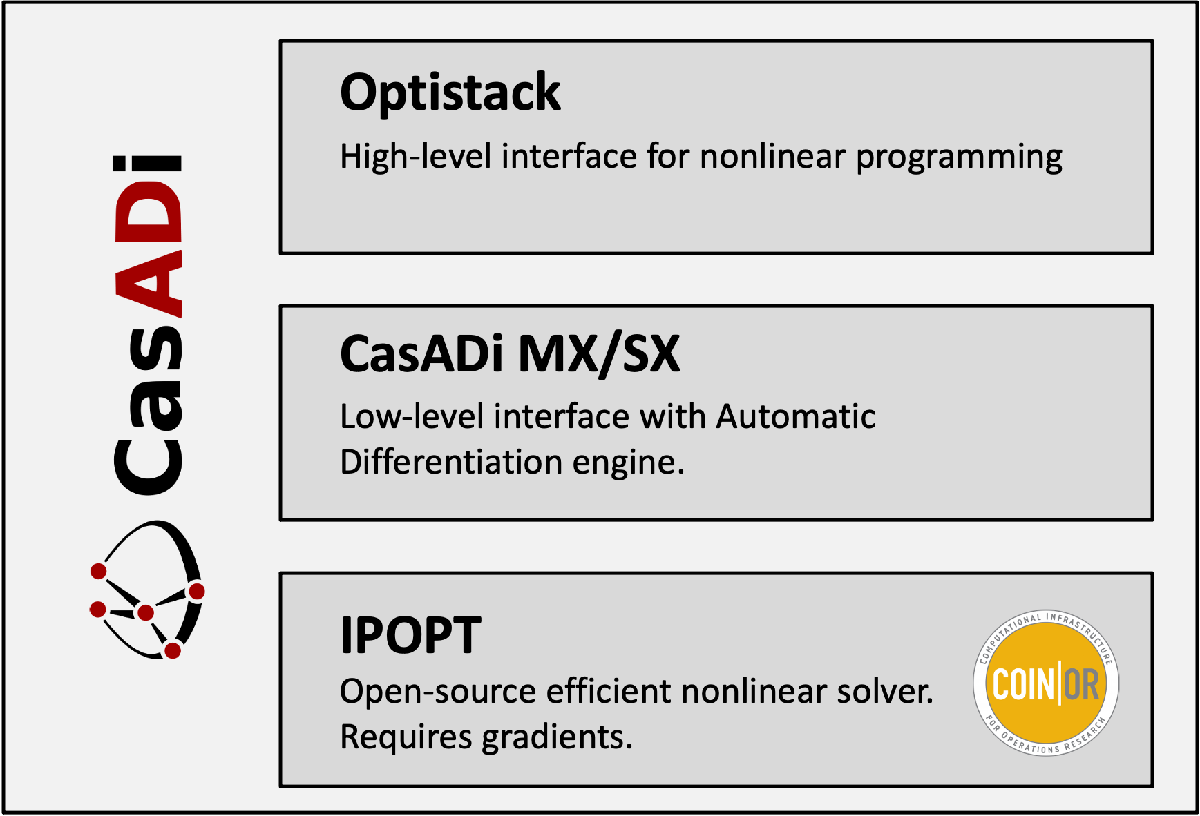

**Where CasADi's Optistack shines**

- Nonlinear nonconvex problems where the cost function's and constraints' gradients are well defined

- Both MATLAB and Python interfaces

- C code generation for embedded controllers

**Limitations**

- Does not support integer variables

- Limited set of functions

(Dobbiamo poter determinare i gradienti di vincoli e funzione da ottimizzare, per poter utlizzare IPOPT)

## Solving an optimization problem with CasADi

Let's try to solve the following dummy problem:

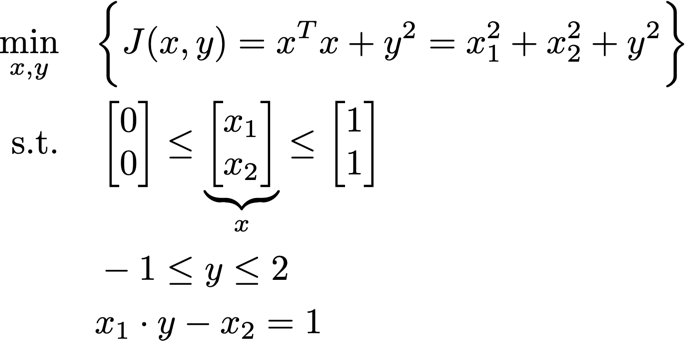

1)** Instantiate the Optimization problem**

Create an "empty" optimization problem called `opti`

import casadi.*
opti = casadi.Opti();

2) **Define the optimization variables**

Use `opti.variable(m, n)` to define an  m-by-n  matrix of optimization variables

x = opti.variable(2, 1); % 2x1 vector of variables
y = opti.variable(1, 1); % scalar variable

3) **Impose the constraints**

opti.subject_to([0; 0] <= x <= [1; 1]);

opti.subject_to(-1 <= y <= 2)

opti.subject_to(x(1) * y - x(2) == 1);

4) **Define the cost function**

J = x.' * x + y^2; % x.'=x' ( in alcuni casi è diverso)
opti.minimize(J);

5) If available, **specify the initial guesses**

Specifying good initial guesses can dramaticaly improve performances

% step opzionale
opti.set_initial(x, [0.5; 0.5])
opti.set_initial(y, 0);

6)** Specify solver and settings**

Some fixed setting to suppress debug messages and solver's printings.

% CASADI settings
prob_opts = struct;
prob_opts.expand = true;
prob_opts.ipopt.print_level = 0;    % Disable printing
prob_opts.print_time = false;       % Do not print the timestamp

% IPOPT settings
ip_opts = struct;
ip_opts.print_level = 0;            % Disable printing
ip_opts.max_iter = 1e5;             % Maximum iterations

% Set the solver
opti.solver('ipopt', prob_opts, ip_opts);

7) **Solve the optimization problem** and retrieve the solutions

The `opti.solve()` instruction launches the resolution of the optimization problem.

try
    sol = opti.solve(); % sol contiene tutte le soluzioni
    x_opt = sol.value(x) % con questi comandi estraiamo le soluzioni ottime
    y_opt = sol.value(y)
catch ME
    keyboard;  % Enter debug mode
end


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit http://projects.coin-or.org/Ipopt
******************************************************************************



x_opt =     1.0000
   -0.0000


y_opt = 1.0000